# Параметры системы

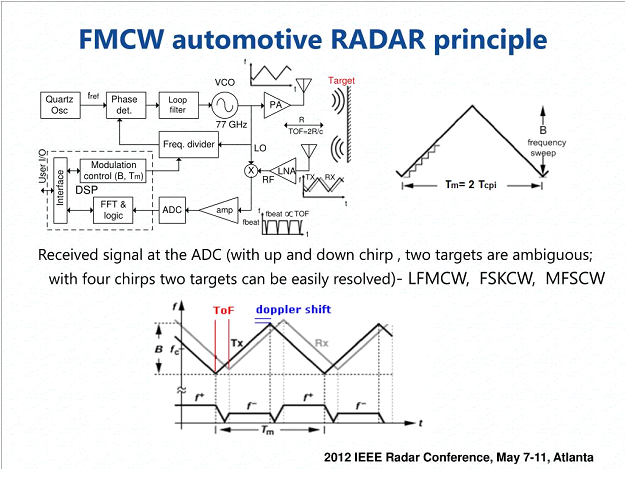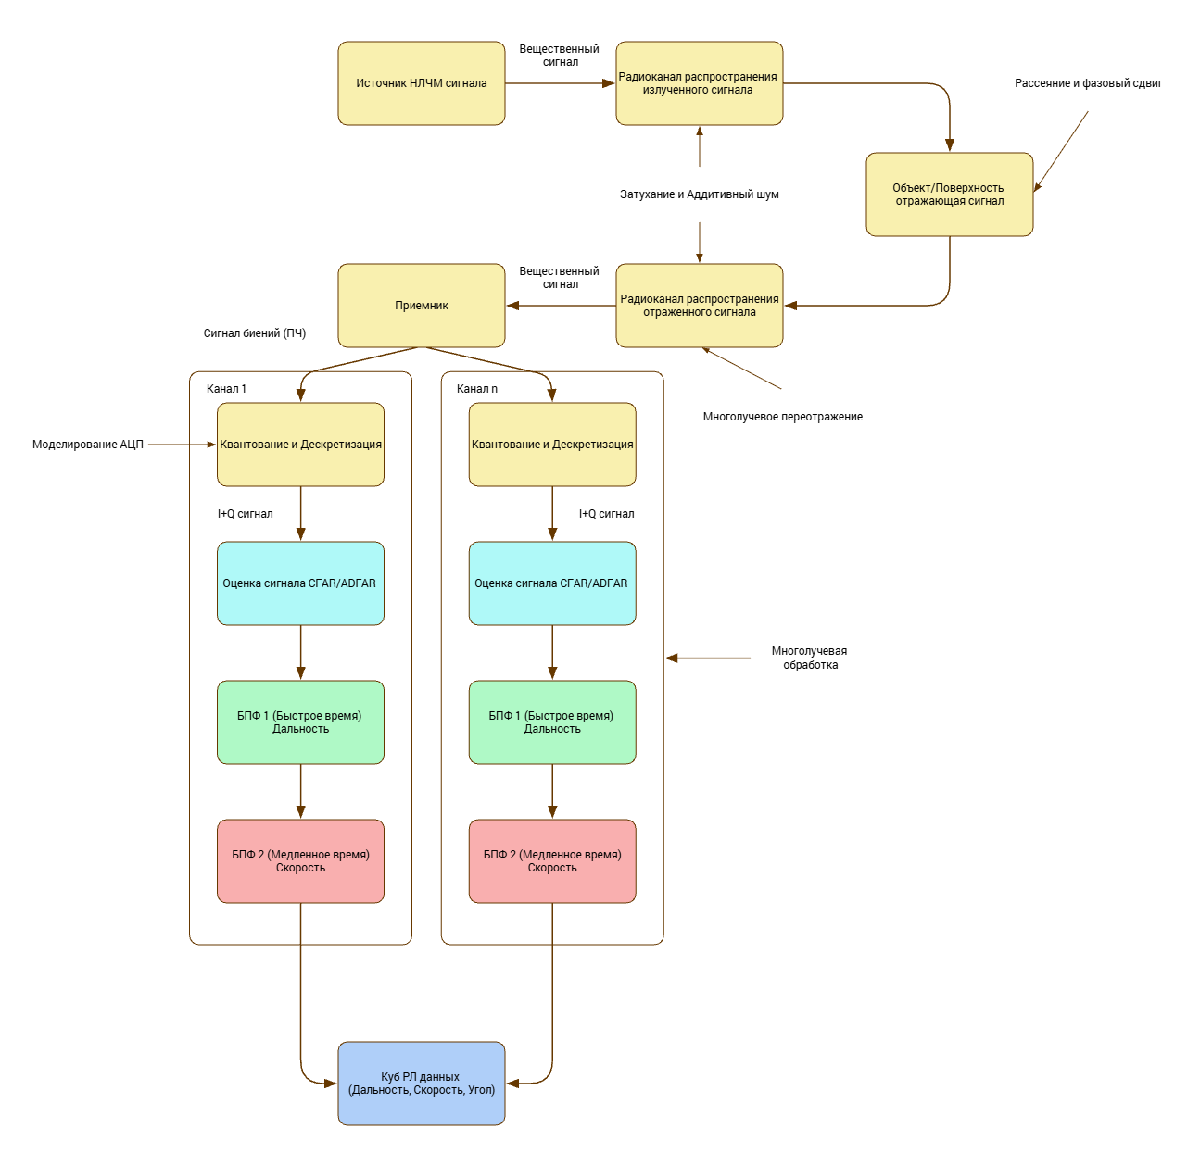

% Параметры полета
flightSpeed = 30;      % Скорость полета, м/с ( ~100 км/ч)
flightHeight = 150;    % Высота платформы м
flightDuration = 2;    % Длительность полета, с 
flightDirection = 0;   % Азимут направления полета, градусы
angleVision = 90;      % Направление антенн РЛС от горизонтали, градусы

c = physconst('LightSpeed');    % Скорость света
fc = 6.0e9;                     % Несущая частота (Гц)
lambda = c/fc;                  % Длина волны
rangeMax = flightHeight * 1.25; % Максимальная дальность (м)
rangeRes = 1;                   % Разешение по дальности

modulationType = 'Sawtooth';    % {'Sawtooth', 'Triangle'}
km = 100;                       % Коэффициент запаса периода модуляции
P_tx = 1;                     % Мощность передатчика (Вт)
noiseFigure = 7;                % Коффициент шума приемника (dB)

Tm = km*range2time(rangeMax,c); % Период модуляции (с)
Bw = rangeres2bw(rangeRes,c);   % Полоса частот ЛЧМ (Гц) 100 МГц = 1,5 м
waveformSamplingRate = 2 * Bw;  % Частота дискретизации (Гц)
sweepSlope = Bw/Tm;             % Муртизна модуляции
T_sweep = Tm;                   % Период чирпа (с) sawtooth
N_Chirp = 1;                    % Число чирпоы в одном интервале обработки Tm

if strcmp(modulationType, 'Triangle')
    T_sweep = Tm / 2;  
    N_Chirp = 2; % Два чирпа в одном интервале обработки: 1 восходящий, 1 нисходящий
else
    modulationType = 'Up';
end



% Максимальаня чатсота сигнала биений для максимальной дальности
fr_max = range2beat(rangeMax,sweepSlope,c);
fd_max = speed2dop(flightSpeed,lambda);
fb_max = fr_max+fd_max; % Максимальная частота биений
fs = max(2*fb_max, Bw); % Частота дескретизации расчетов
fs = round(fs * T_sweep) / T_sweep; % коррекция fs для целого числа отсчетов


## Параметры антенны

antBeamwidth = 45;       % Ширина ДН антенны (градусы)
% az_antBeamwidth = 5;     % Ширина ДН по азимуту (градусы)
% el_beamwidth = 30;    % Ширина ДН по углу места (градусы)
antennaGain = 15;      % Коэффициент усиления антенны (дБи)

% Расчет антенны
frequencyRange = [fc-Bw/2 fc+Bw/2];

% % 1 Из патч антенн 
% patchElement = design(patchMicrostrip,fc);
% patchElement.Tilt = 90;
% patchElement.TiltAxis = [0 1 0];
% 
% myFigure = gcf;
% myFigure.Color = 'w';
% pattern(patchElement,fc)
% figure;
% Numfreqs = 21;
% freqsweep = unique([linspace(fc-Bw/2, fc+Bw/2, Numfreqs) fc]);
% impedance(patchElement,freqsweep);
% 
% figure;
% s = sparameters(patchElement,freqsweep);
% rfplot(s,'m-.')
% hold on
% line(freqsweep/1e9,ones(1,numel(freqsweep))*-10,'LineWidth',1.5)
% hold off

% % Антенная решетка
% fc2 = fc+Bw/2; % Верхняя частота
% lambda_fc2 = c/fc2;
% fmcwPatchArray = phased.URA;
% fmcwPatchArray.Element = patchElement;
% Nrow = 2;
% Ncol = 4;
% fmcwPatchArray.Size = [Nrow Ncol];
% fmcwPatchArray.ElementSpacing = [0.5*lambda_fc2 0.5*lambda_fc2];
% az = -180:5:180;
% el = -90:5:90;
% clf
% pattern(fmcwPatchArray,fc,az,el)

% % 2 АР с косинусной ДН
% cosineantenna = phased.CosineAntennaElement('FrequencyRange', frequencyRange);;
% pattern(cosineantenna,fc)
% 
% Nrow = 2;
% Ncol = 4;
% antArray = phased.URA;
% antArray.Element = cosineantenna;
% antArray.Size = [Nrow Ncol];
% antArray.ElementSpacing = [0.5*lambda 0.5*lambda];

% figure
% patternAzimuth(fmcwPatchArray,fc)
% hold on
% patternElevation(fmcwPatchArray,fc)
% p = polarpattern('gco');
% p.LegendLabels = {'Azimuth','Elevation'};
% beamwidth(fmcwPatchArray, fc);

% % 3 Ненаправленная антенна
% antenna = phased.IsotropicAntennaElement('FrequencyRange', frequencyRange);

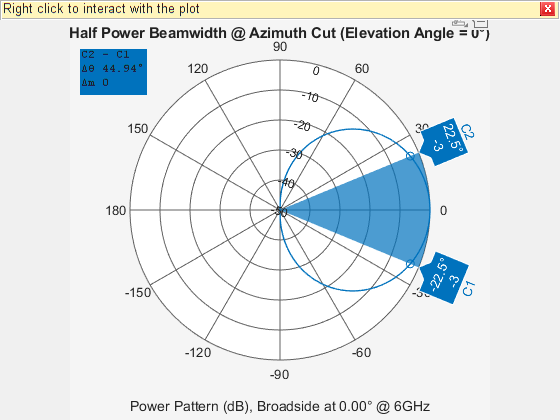

% 4 Гауссова ДН по заданным параметрам
antennaElement = phased.GaussianAntennaElement("Beamwidth",antBeamwidth,"FrequencyRange",frequencyRange);

% Plot the beamwidth to verify that it matches the expected antenna beamwidth
beamwidth(antennaElement, fc);

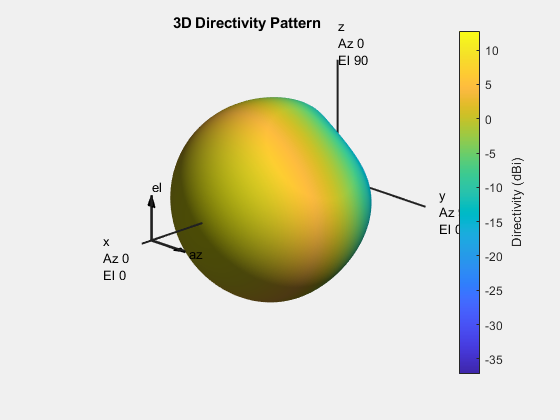

pattern(antennaElement,fc)

## Передатчик и приемник

txAmp = 10;  % in dB
txGain = txAmp + antennaGain % in dB

txGain = 25

transmitter = phased.Transmitter('PeakPower', P_tx, ...
                                'Gain', antennaGain);
                                % 'InUseOutputPort', true);
% Приемник с МШУ
rxAmp = 40;  % in dB
rxGain = rxAmp + antennaGain % in dB

rxGain = 55

receiver = phased.ReceiverPreamp('Gain', rxGain, ...      % Усиление МШУ
                                'NoiseFigure', noiseFigure, ... % Коэффициент шума 1.5 дБ
                                'ReferenceTemperature', 290, ... % Абсолютная температура
                                'SampleRate', waveformSamplingRate);
                                % 'EnableInputPort', true);


## Канал распространения

channel = phased.FreeSpace('PropagationSpeed', c, 'OperatingFrequency', fc, ...
    'SampleRate', fs, 'TwoWayPropagation', true);


## Создание огибающей FMCW сигнала

waveform = phased.FMCWWaveform('SampleRate', fs, ...
                               'SweepTime', T_sweep, ...
                               'SweepBandwidth', Bw, ...
                               'SweepDirection', modulationType, ...
                               'OutputFormat', 'Sweeps', ...
                               'NumSweeps', N_Chirp);

% Генерация сигнала
sig = waveform();

% Создание вектора времени
total_samples = length(sig);
t = (0:total_samples-1) / fs;


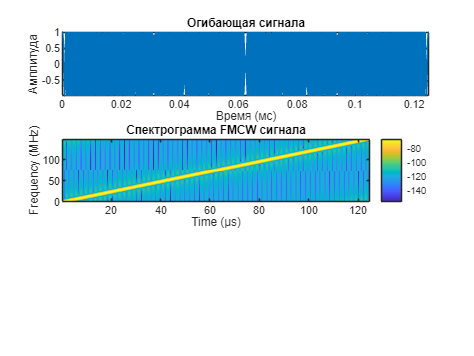

% Построение графиков
figure;

% График сигнала во времени
subplot(311);
plot(t * 1000, real(sig)); % Время в миллисекундах
xlabel('Время (мс)');
ylabel('Амплитуда');
title('Огибающая сигнала');
grid on;
axis tight;

% Спектрограмма
subplot(312);
window_length = 64;
overlap = 32;
nfft = 128;
spectrogram(sig, window_length, overlap, nfft, fs, 'yaxis');
title('Спектрограмма FMCW сигнала');
colorbar;


% % Спектрограмма с другими параметрами
% subplot(313); 
% spectrogram(sig, 32, 16, 32, waveformSamplingRate, 'yaxis');
% title('Спектрограмма FMCW сигнала');
% colorbar;


## Создание произвольной поверхности и карты ЭПР поверхности

% Параметры поверхности
surface_size = 500;        % Размер области поверхности, м
grid_resolution = 2;        % Разрешение сетки, м
x_surface = -surface_size/2:grid_resolution:surface_size/2;
y_surface = -surface_size/2:grid_resolution:surface_size/2;
[X_surf, Y_surf] = meshgrid(x_surface, y_surface);

% Создание сложной топографии (холмы, долины, случайные неровности)
% Большие формы рельефа
Z_surf = 20 * sin(X_surf/100) .* cos(Y_surf/80) + ...          % Крупные холмы
         10 * sin(X_surf/50 + pi/4) .* sin(Y_surf/60) + ...    % Средние формы
         5 * cos(X_surf/30) .* cos(Y_surf/40 + pi/3) + ...     % Мелкие холмы
         2 * randn(size(X_surf));                              % Случайная шероховатость

% Добавление резких перепадов (обрывы, овраги)
cliff_mask = (X_surf > -50 & X_surf < 50 & Y_surf > -100 & Y_surf < -50);
Z_surf(cliff_mask) = Z_surf(cliff_mask) - 15;

% Расчет ЭПР поверхности (зависит от типа местности и угла)
surface_rcs_base = -20;     % ЭПР поверхности земли, дБм²
surface_rcs_variation = 10;  % Вариация ЭПР, дБ

% Различные типы поверхности в зоне полета
forest_mask = (X_surf.^2 + Y_surf.^2) < 200^2;                % Лесистая область
water_mask = (X_surf > 100 & X_surf < 300 & Y_surf > -200 & Y_surf < 0); % Водная поверхность
urban_mask = (X_surf > -300 & X_surf < -100 & Y_surf > 50 & Y_surf < 200); % Городская застройка

% Расчет ЭПР с учетом типа поверхности
RCS_surf = surface_rcs_base * ones(size(X_surf)) + ...
           surface_rcs_variation * randn(size(X_surf));

% Корректировка ЭПР для различных типов поверхности
RCS_surf(forest_mask) = RCS_surf(forest_mask) + 5;     % Лес -15 дБм²
RCS_surf(water_mask) = RCS_surf(water_mask) - 20;      % Вода - 40 дБм²
RCS_surf(urban_mask) = RCS_surf(urban_mask) + 10;      % Город - 10 дБм²


## Вычисление ЭПР поверхности для каждого шага

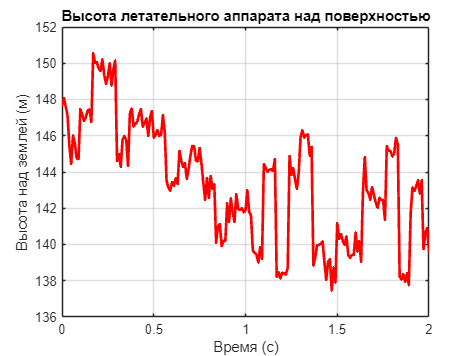

dt = 0.01;                  % Шаг по времени, с
t_flight = 0:dt:flightDuration;
n_samples = length(t_flight);

% Прямолинейный полет
flight_x = flightSpeed * t_flight * cosd(flightDirection);
flight_y = flightSpeed * t_flight * sind(flightDirection);
flight_z = flightHeight * ones(size(t_flight));

% Добавление небольших флуктуаций высоты (турбулентность)
altitude_noise = 0.5 * randn(size(t_flight));  % ±0.5м вариации высоты
flight_z = flight_z + altitude_noise;


%% Расчет высоты над поверхностью прямо под ЛА

Rg_under_LA = zeros(size(t_flight));  % Массив для хранения высоты над землей

% Получим шаги сетки поверхности
dx = X_surf(1,2) - X_surf(1,1);
dy = Y_surf(2,1) - Y_surf(1,1);

for i = 1:length(t_flight)
    % Координаты ЛА
    x = flight_x(i);
    y = flight_y(i);
    
    % Индексы ближайшей точки на сетке
    idx_x = round((x - X_surf(1,1)) / dx) + 1;
    idx_y = round((y - Y_surf(1,1)) / dy) + 1;
    
    % Проверка выхода за границы
    if idx_x >= 1 && idx_x <= size(Z_surf, 2) && ...
       idx_y >= 1 && idx_y <= size(Z_surf, 1)
        z_ground = Z_surf(idx_y, idx_x);  % Высота земли под ЛА
    else
        z_ground = 0;  % Если вышли за пределы сетки
    end
    
    % Дальность до земли под ЛА
    Rg_under_LA(i) = flight_z(i) - z_ground;
end

%% Построение графика
figure;
plot(t_flight, Rg_under_LA, 'r', 'LineWidth', 2);
grid on;
xlabel('Время (с)');
ylabel('Высота над землей (м)');
title('Высота летательного аппарата над поверхностью');

%% Создание целей поверхности для каждого момента времени

% Параметры облучаемой области
footprint_size = 2 * flightHeight * tand(antBeamwidth/2); % Размер пятна облучения


% Создание массива целей поверхности (используем cell arrays)
surface_targets = {};
surface_positions = {};
surface_rcs_values = [];

for i = 1:length(t_flight)
    % Текущее положение носителя
    aircraft_pos = [flight_x(i); flight_y(i); flight_z(i)];
    

    % Поиск точек поверхности в пределах пятна антенны
    dx = X_surf - flight_x(i);
    dy = Y_surf - flight_y(i);
    dz = Z_surf;
    
    % Расстояние до каждой точки поверхности
    ranges = sqrt(dx.^2 + dy.^2 + (flight_z(i) - dz).^2);
    
    % Угол от надира
    nadir_angles = acosd((flight_z(i) - dz) ./ ranges);
    
    % Выбор точек в пределах луча антенны
    in_beam = (nadir_angles <= antBeamwidth/2) & (ranges <= rangeMax);
    
    if sum(in_beam(:)) > 0
        % Выбираем репрезентативные точки (прореживание для эффективности)
        [beam_i, beam_j] = find(in_beam);
        
        % Прореживание точек (каждую 5-ю точку)
        subsample_idx = 1:5:length(beam_i);
        if ~isempty(subsample_idx)
            selected_i = beam_i(subsample_idx);
            selected_j = beam_j(subsample_idx);
            
            for k = 1:length(selected_i)
                target_x = X_surf(selected_i(k), selected_j(k));
                target_y = Y_surf(selected_i(k), selected_j(k));
                target_z = Z_surf(selected_i(k), selected_j(k));
                target_rcs = db2pow(RCS_surf(selected_i(k), selected_j(k)));
                
                
                % Создание цели
                surface_target = phased.RadarTarget('MeanRCS', target_rcs, ...
                    'PropagationSpeed', c, 'OperatingFrequency', fc);
                
                % Неподвижная цель (поверхность)
                target_motion = phased.Platform('InitialPosition', [target_x; target_y; target_z], ...
                    'Velocity', [0; 0; 0]);
                
                surface_targets{end+1} = surface_target;
                surface_positions{end+1} = target_motion;
                surface_rcs_values = [surface_rcs_values, target_rcs];
            end
        end
    end
end

fprintf('Создано %d целей поверхности\n', length(surface_targets));


## Платформа носителя

aircraft_platform = phased.Platform('InitialPosition', [flight_x(1); flight_y(1); flight_z(1)], ...
    'Velocity', [flightSpeed * cosd(flightDirection); flightSpeed * sind(flightDirection); 0]);

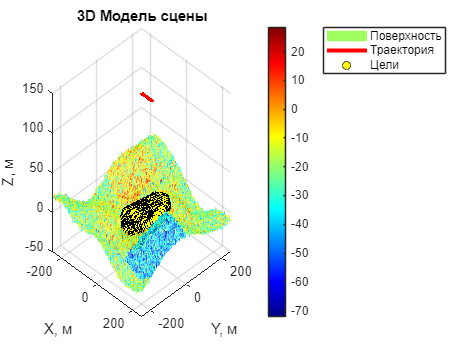

% 3D визуализация сцены
figure;
surf(X_surf, Y_surf, Z_surf, RCS_surf, 'EdgeColor', 'none', 'FaceAlpha', 0.7);
hold on;
plot3(flight_x, flight_y, flight_z, 'r-', 'LineWidth', 3);
if ~isempty(surface_targets)  
    x_coords = cellfun(@(s) s.InitialPosition(1), surface_positions);
    y_coords = cellfun(@(s) s.InitialPosition(2), surface_positions);
    z_coords = cellfun(@(s) s.InitialPosition(3), surface_positions);
    
    scatter3(x_coords, y_coords, z_coords, 50, 'filled', ...
             'MarkerFaceColor', 'yellow', 'MarkerEdgeColor', 'black');
end
xlabel('X, м'); ylabel('Y, м'); zlabel('Z, м');
title('3D Модель сцены');
colorbar; colormap(jet);
legend('Поверхность', 'Траектория', 'Цели');
grid on; view(45, 30);


% Дальность до земли


## Моделирование

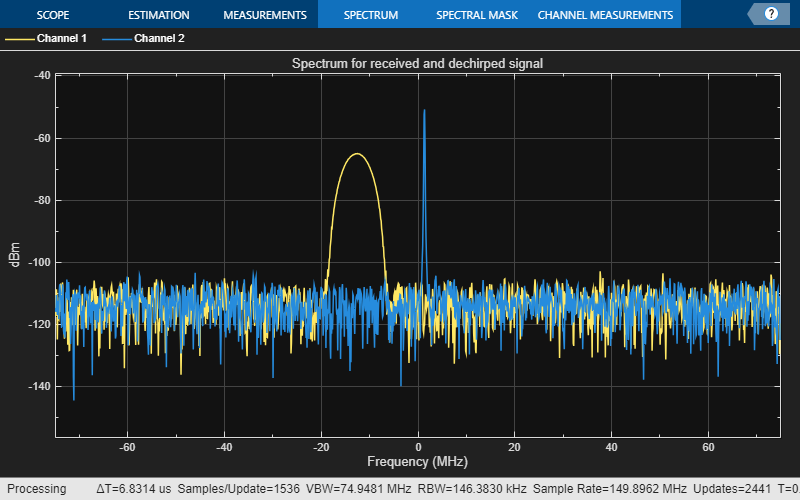

specanalyzer = spectrumAnalyzer('SampleRate',fs, ...
    'Method','welch','AveragingMethod','running', ...
    'PlotAsTwoSidedSpectrum',true, 'FrequencyResolutionMethod','rbw', ...
    'Title','Spectrum for received and dechirped signal', ...
    'ShowLegend',true);

rng(2025);
% SAR использует накопление эхо-сигналов в течение движения радара,
% что требует не одного свипа, а нескольких (Nsweep) на протяжении
% интервала х × Tm
accumTime = 2 * Tm;
propagation_time = range2time(rangeMax);
N_sweep = round(accumTime / propagation_time);      % 64; Количество интервалов для синтеза аппертуры
xr = complex(zeros(waveform.SampleRate*waveform.SweepTime,N_sweep));
radar_pos_all = zeros(3, N_sweep);
tgt_pos_all = zeros(3, N_sweep);

for m = 1:N_sweep
    % Обновление положени радара и целей
    [radar_pos,radar_vel] = aircraft_platform(waveform.SweepTime);
    [tgt_pos,tgt_vel] = target_motion(waveform.SweepTime);
     
    % Сохранение позиций радара и целей для каждого свипа
    radar_pos_all(:, m) = radar_pos;
    tgt_pos_all(:, m) = tgt_pos;

    % Transmit FMCW waveform
    sig = waveform();
    txsig = transmitter(sig);

    % Propagate the signal and reflect off the target
    txsig = channel(txsig,radar_pos,tgt_pos,radar_vel,tgt_vel);
    txsig = surface_target(txsig);

    % Dechirp the received radar return
    txsig = receiver(txsig);
    dechirpsig = dechirp(txsig,sig);

    % Visualize the spectrum
    specanalyzer([txsig dechirpsig]);
    
    % Фазовая компенсация движения радара
    range_to_center = norm(tgt_pos - radar_pos); 
    phase_shift = exp(1j * 4 * pi * range_to_center / lambda);
    xr(:, m) = dechirpsig .* phase_shift;
end

## Обработка SAR

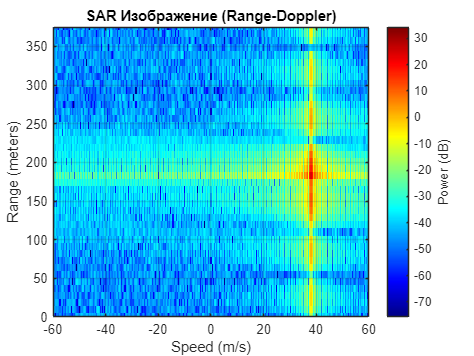

% Создание раиолокационного кадра
rngdopresp = phased.RangeDopplerResponse('PropagationSpeed',c,...
    'DopplerOutput','Speed','OperatingFrequency',fc,'SampleRate',fs,...
    'RangeMethod','FFT','SweepSlope',sweepSlope,...
    'RangeFFTLengthSource','Property','RangeFFTLength',2048,...
    'DopplerFFTLengthSource','Property','DopplerFFTLength',512);

clf;
plotResponse(rngdopresp,xr);                     % Грфик Расстояние и доплеровское смещение

axis([-flightSpeed*2 2*flightSpeed 0 2*rangeMax])
grid on;
title('SAR Изображение (Range-Doppler)');

% Оценка высоты и скорости за период синтезирования
climVals = clim;
Dn = fix(fs/(2*fb_max));
for m = size(xr,2):-1:1
    xr_d(:,m) = decimate(xr(:,m),Dn,'FIR');
end
fs_d = fs/Dn;
fb_rng = rootmusic(pulsint(xr_d,'coherent'),1,fs_d);
rng_est = beat2range(fb_rng,sweepSlope,c)

rng_est = 178.9377

peak_loc = val2ind(rng_est,c/(fs_d*2));
fd = -rootmusic(xr_d(peak_loc,:),1,1/Tm);
v_est = dop2speed(fd,lambda)/2

v_est = 38.0800